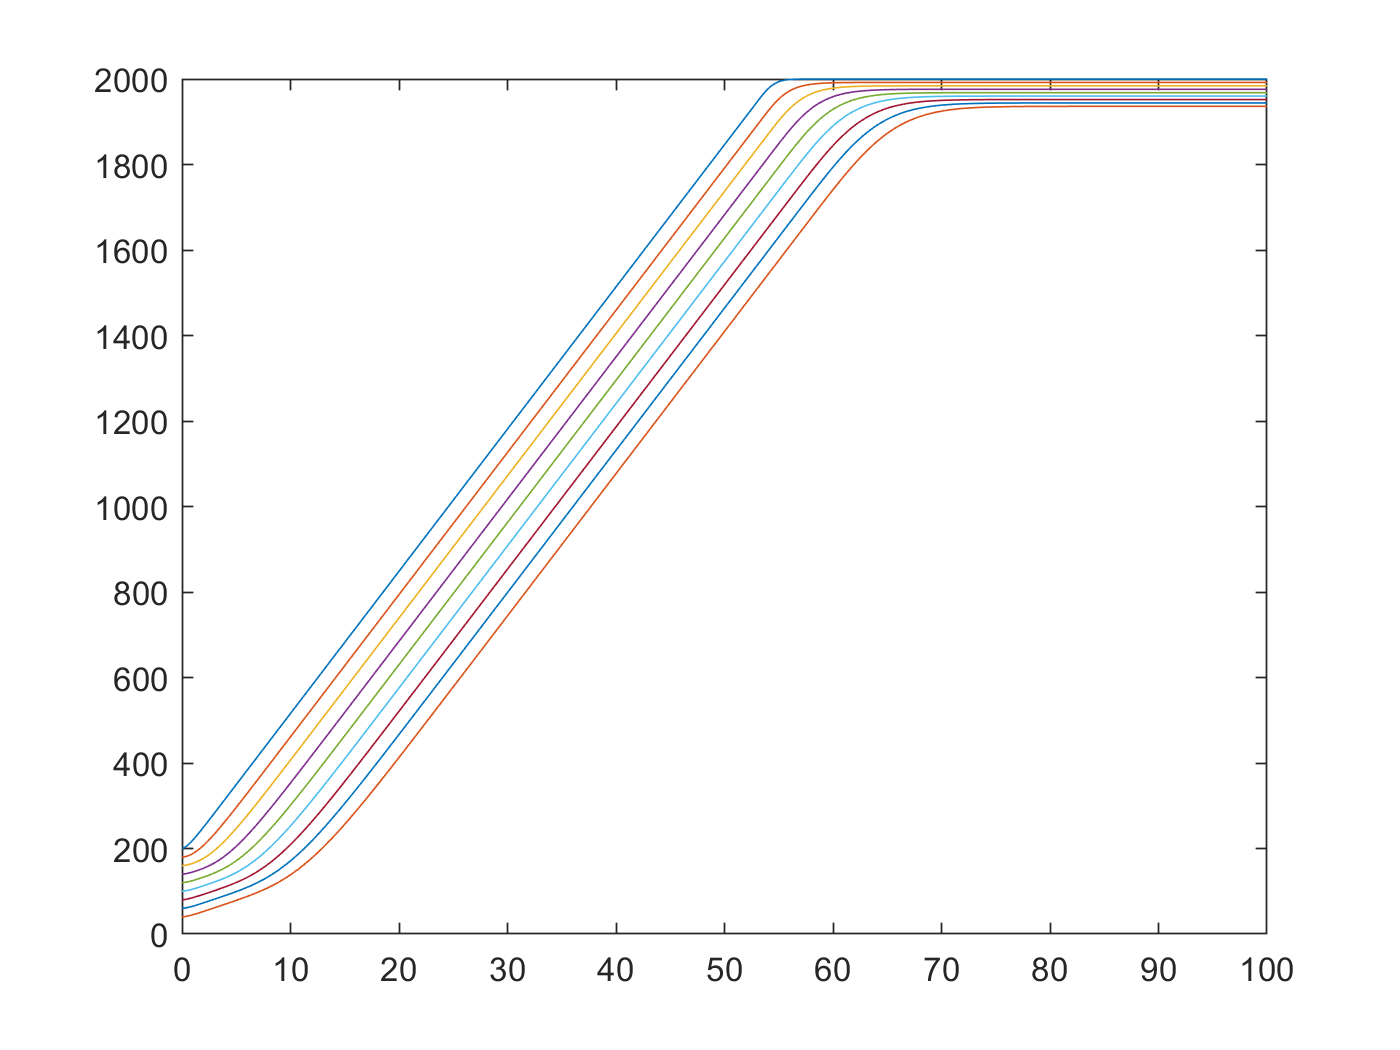

clear 
num_c = 9;  % number of cars 

% Initial Conditions 
% Note: The index of the car corresponds to the order of the car. (Ex: Car 1
% is in the first element of the vector)
pos_0 = linspace(200, 40, num_c); % Initial position of cars.
vel_0 = zeros(1,num_c); % Initial velocity of cars. 
acc_0 = zeros(1,num_c); % Inital acceleration of cars.

% Characteristic of cars and road. 
lengths = ones(1,num_c)*5; % Length of cars. 
gamma = 0.6; % Speed difference sensitivity. 
x_destination = 2000; % Destination.

% Parameters for Numerical Integration
tstep = 0.1;
t_final = 100;
numsteps = round(t_final/tstep);

% Default initialize an array and set parameters for the vehicles. 
vehiclesInOrder(1:num_c) = Vehicle(); 
for i = 1:num_c
    vehiclesInOrder(i) = Vehicle(pos_0(i), vel_0(i), acc_0(i), lengths(i));
end

% Create array to store time, position, velocity, acceleration, and gap.
tvals = linspace(0, t_final, numsteps);
xvals = zeros(numsteps, num_c);
vvals = zeros(numsteps, num_c);
avals = zeros(numsteps, num_c);
gvals = zeros(numsteps, num_c);

for t = 1:numsteps
    for i = num_c:-1:1 % Loop through the car starting with the last car.
        
        next = i;
        while(1)
            if next < 2
                next = i;
            else
                next = next-1;
            end
                        
            if vehiclesInOrder(next).lane == vehiclesInOrder(i).lane
                break;
            end
        end
        % set leading vehicle velocity to speed limit if no cars is in front
        if i == next  % First car. 
            % Find gap using first car's position and destination.
            % Use velocity of itself.
            s = x_destination - vehiclesInOrder(i).state(1); 
            v_l = vehiclesInOrder(i).state(2);
        else % Cars after the first car.
            % Compute gap and use velocity using the car in front of it.            
            s = vehiclesInOrder(next).state(1) - vehiclesInOrder(next).width - vehiclesInOrder(i).state(1); 
            v_l = vehiclesInOrder(next).state(2);
        end
        % Compute gap and state variables. 
        newstate = vehiclesInOrder(i).timestep(s, v_l, tstep, gamma);
        gvals(t, i) = s;
        xvals(t, i) = newstate(1);
        vvals(t, i) = newstate(2);
        avals(t, i) = newstate(3);
      
    end
    
    vehiclesInOrder = Vehicle.sortCars(vehiclesInOrder);
end

% Graph position versus time. 
for i = 1:num_c
    plot(tvals, xvals(:,i))
    hold on;
end
hold off;

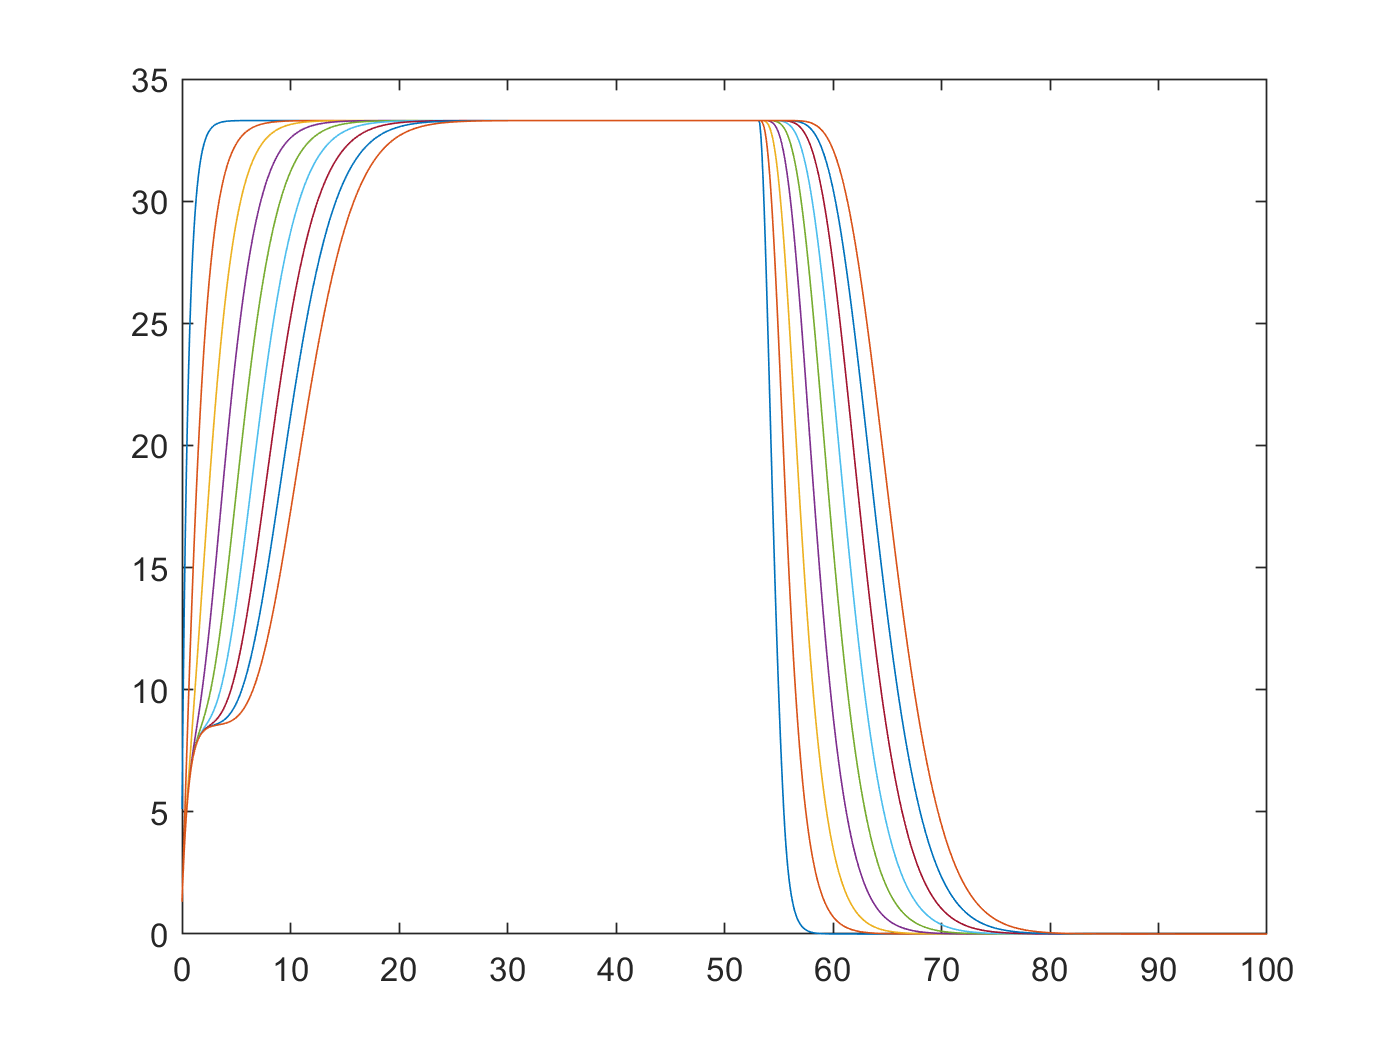

% Graph velocity versus time.
for i = 1:num_c
    plot(tvals, vvals(:,i))
    hold on;
end
hold off;

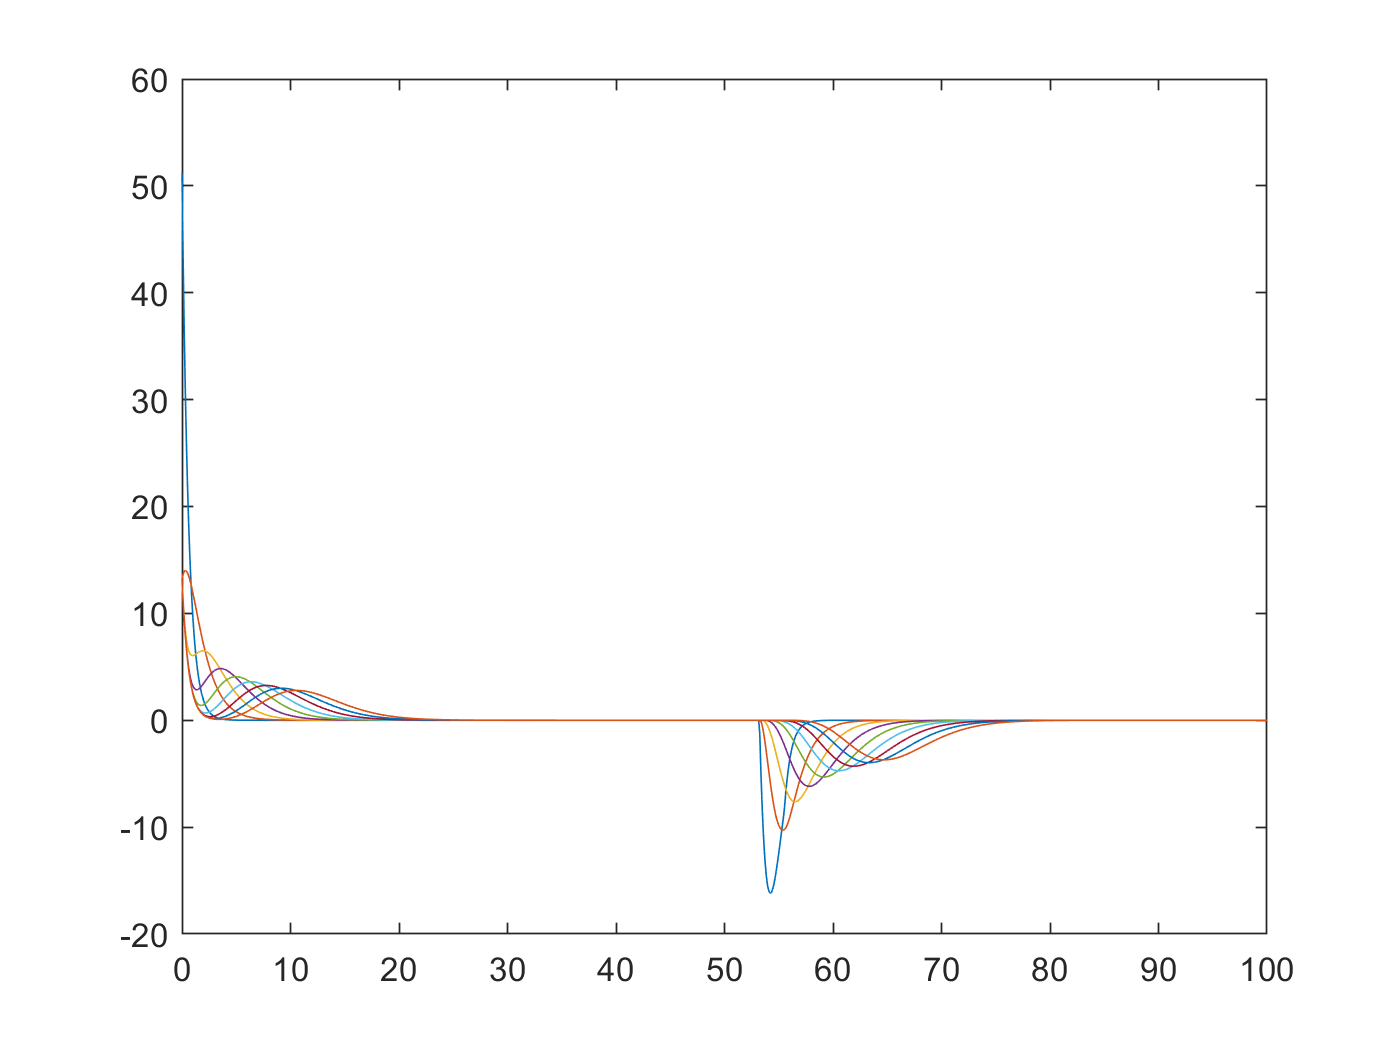

% Graph acceleration versus time.
for i = 1:num_c
    plot(tvals, avals(:,i))
    hold on;
end
hold off;

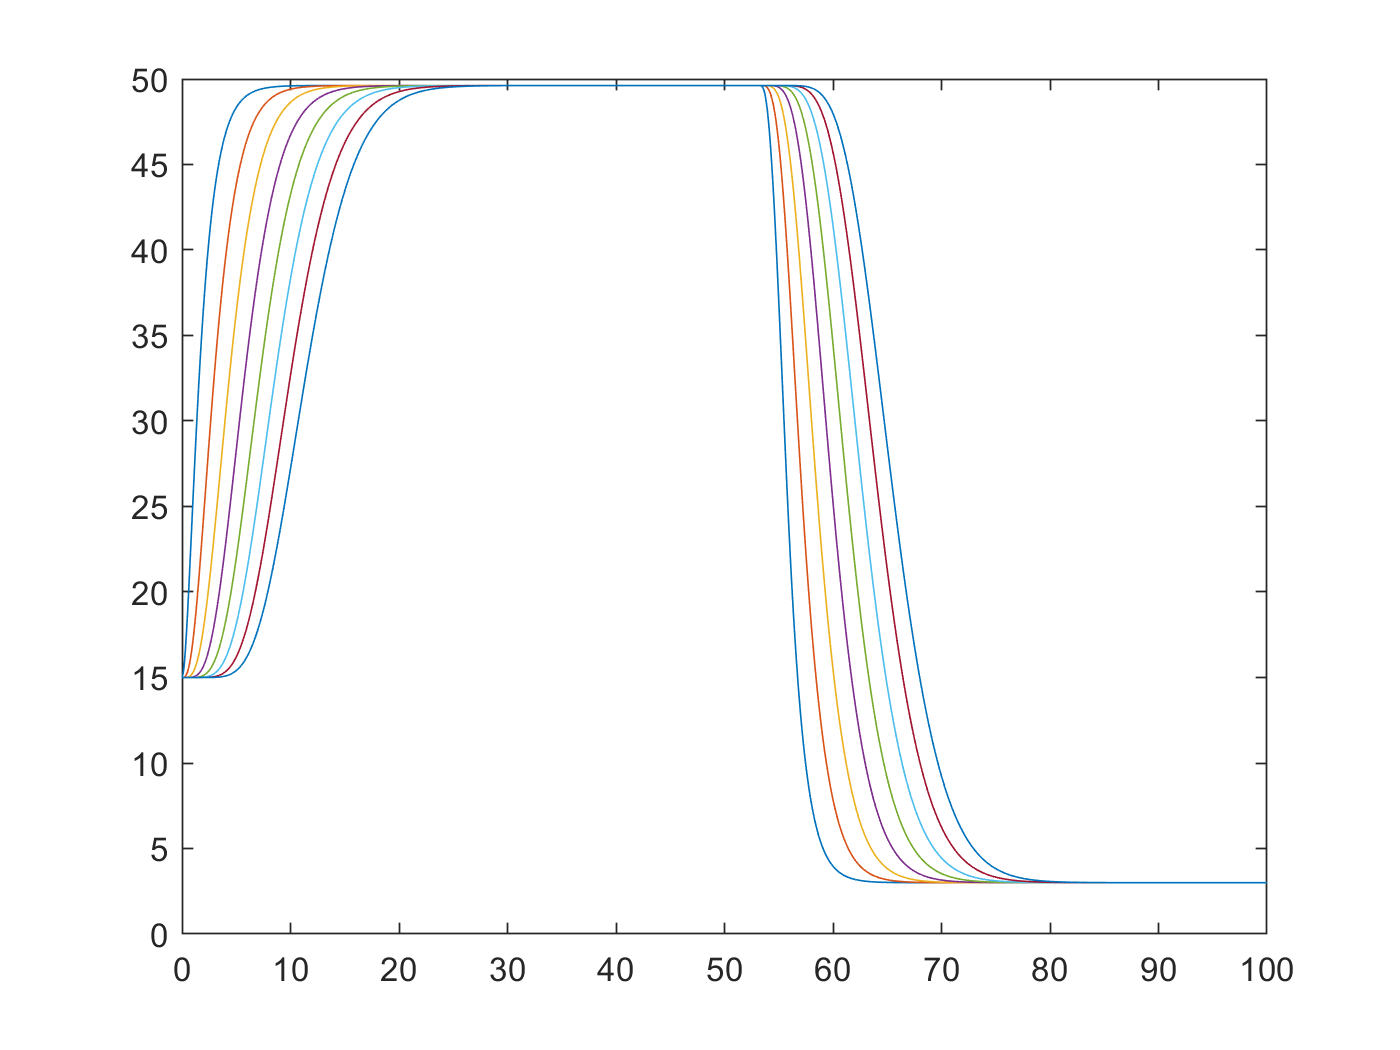

% Graph gap versus time.
for i = 2:num_c
    plot(tvals, gvals(:,i))
    hold on;
end
hold off;